% NEWTONS_METHOD  Newton–Raphson root-finding algorithm
tic;
%%   Inputs:
x0   = 1                      %Initial guess for the root
f    =@(x) x.^2 - 2           %Function handle whose root we want to find
f_prime =@(x) 2.*x            %Derivative of the function (function handle)

x0 = 0.5000

f = function_handle with value:
    @(x)x.^3-2.*x+2


f_prime = function_handle with value:
    @(x)3.*x.^2-2



tolerance = 1e-8              %Stop if successive estimates differ by less than this

tolerance = 1.0000e-08

epsilon   = 1e-10             %Avoid division if derivative magnitude < epsilon

epsilon = 1.0000e-10

max_iterations = 100          %Maximum allowed number of iterations

max_iterations = 100


%% Output

root = newtons_method(x0, f, f_prime, tolerance, epsilon, max_iterations)

Iter 1 
 x = 1.400000e+00 
Iter 2 
 x = 8.989691e-01 
Iter 3 
 x = -1.288779e+00 
Iter 4 
 x = -2.105767e+00 
Iter 5 
 x = -1.829200e+00 
Iter 6 
 x = -1.771716e+00 
Iter 7 
 x = -1.769297e+00 
Iter 8 
 x = -1.769292e+00 
Iter 9 
 x = -1.769292e+00 .
Converged after 9 iterations.


root = -1.7693



toc;

Elapsed time is 0.030875 seconds.


## Some extra functions and derivatives to try with different initial guess

% (1)
% x0   = 0                      %Initial guess for the root
% f    =@(x) exp(-x) - x        %Function handle whose root we want to find
% f_prime =@(x) -exp(-x) - 1    %Derivative of the function (function handle)

% (2)
% x0   = 0                      %Initial guess for the root
% f    =@(x) cos(x) - x         %Function handle whose root we want to find
% f_prime =@(x) -sin(x) - 1     %Derivative of the function (function handle)

% (3)
% x0   = 2                       %Initial guess for the root
% f    =@(x) x.^3-2.*x+2         %Function handle whose root we want to find
% f_prime =@(x) 3.*x.^2 - 2      %Derivative of the function (function handle)

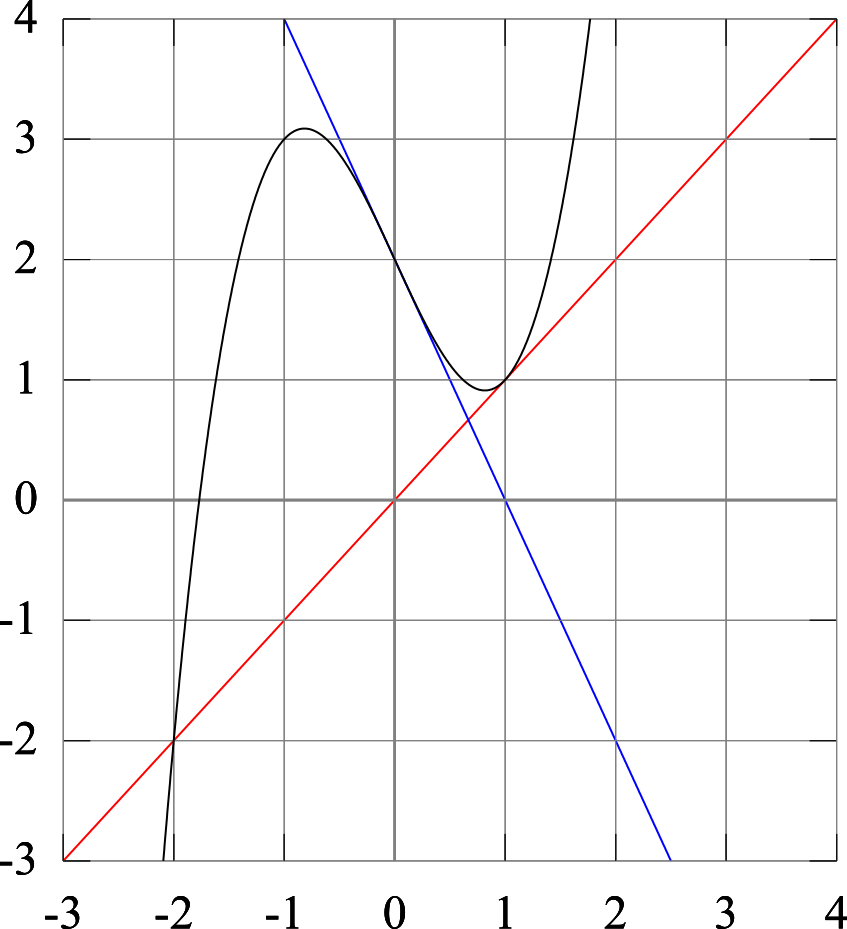       Source: [Wikipedia](https://en.wikipedia.org/wiki/Newton's_method#)

% (4)
% x0   = 0.1                          %Initial guess for the root 
%                                     % (should not be zero)
% f    =@(x) exp(-x) - log(x)         %Function handle whose root we want to find
% f_prime =@(x) -exp(-x) - 1./x       %Derivative of the function (function handle)